## Data Reading

clc; clear all; close all;
% Load Data
data = readtable('data/Spectral_Soft_Sensor_1.csv', 'ReadVariableNames', true);

% setting the first variable = null to exclude the row num col
data.Var1 = [];
disp(data.Properties.VariableNames(1:20)')

    {'AnthocyaninContent__g_cm__'}
    {'BoronContent_mg_cm__'      }
    {'CContent_mg_cm__'          }
    {'CaContent_mg_cm__'         }
    {'CarotenoidContent__g_cm__' }
    {'Cellulose_mg_cm__'         }
    {'ChlContent__g_cm__'        }
    {'CopperContent_mg_cm__'     }
    {'EWT_mg_cm__'               }
    {'Fiber_mg_cm__'             }
    {'LAI_m__m__'                }
    {'LMA_g_m__'                 }
    {'Lignin_mg_cm__'            }
    {'MagnesiumContent_mg_cm__'  }
    {'ManganeseContent_mg_cm__'  }
    {'NContent_mg_cm__'          }
    {'NSC_mg_cm__'               }
    {'PhosphorusContent_mg_cm__' }
    {'PotassiumContent_mg_cm__'  }
    {'SulfurContent_mg_cm__'     }



## Selecting 5 Traits for Regression

%% Selection of Traits - Based on missing values
traitVars = data.Properties.VariableNames(1:20);

traitsNumeric = str2double(string(table2array(data(:, traitVars))));

missingPct = mean(isnan(traitsNumeric), 1) * 100;

[missingPctSorted, sortIdx] = sort(missingPct, 'ascend');
sortedTraits = traitVars(sortIdx);

selectedTraits = sortedTraits(1:5);

disp(table(sortedTraits', missingPctSorted', ...
    'VariableNames', {'Trait', 'MissingPercent'}));

                Trait                 MissingPercent
    ______________________________    ______________

    {'LMA_g_m__'                 }        35.025    
    {'NContent_mg_cm__'          }        49.319    
    {'CContent_mg_cm__'          }        54.713    
    {'ChlContent__g_cm__'        }        56.084    
    {'EWT_mg_cm__'               }        61.396    
    {'Lignin_mg_cm__'            }        64.631    
    {'CarotenoidContent__g_cm__' }        64.992    
    {'Cellulose_mg_cm__'         }        65.008    
    {'Fiber_mg_cm__'             }        65.542    
    {'PhosphorusContent_mg_cm__' }        67.217    
    {'MagnesiumContent_mg_cm__'  }        67.841    
    {'CopperContent_mg_cm__'     }        68.276    
    {'NSC_mg_cm__'               }        68.563    
    {'BoronContent_mg_cm__'      }        68.686    
    {'CaContent_mg_cm__'         }        69.499    
    {'LAI_m__m__'             

disp('Selected traits (lowest missing %):');

Selected traits (lowest missing %):


disp(selectedTraits');

    {'LMA_g_m__'         }
    {'NContent_mg_cm__'  }
    {'CContent_mg_cm__'  }
    {'ChlContent__g_cm__'}
    {'EWT_mg_cm__'       }



## Data Split Between Respose (Traits) and Independent (Spectra) Variables

% Splitting as X and Y
traitNames = {'LMA_g_m__', 'NContent_mg_cm__', ...
              'CContent_mg_cm__', 'ChlContent__g_cm__', 'EWT_mg_cm__'};
% IMPORTANT: Brief explanations of these contents would look good in the report

% Spectral bands
X = str2double(string(table2array(data(:, 21:end)))); % spectral bands start from column 21

% Traits
Y = str2double(string(table2array(data(:, traitNames))));

% Getting back the column names
traitLables = {'LMA (g/m²)', 'N content (mg/cm²)', ...
          'C content (mg/cm²)', 'Chl content (μg/cm²)', 'EWT (mg/cm²)'};

fprintf('Loaded dataset: %d samples, %d spectral bands, %d traits\n', ...
        size(X,1), size(X,2), size(Y,2));

Loaded dataset: 12180 samples, 1721 spectral bands, 5 traits



% Remove rows where any of the traits are missing
validIdx = all(~isnan(Y), 2);
X = X(validIdx, :);
Y = Y(validIdx, :);

fprintf('Valid samples retained: %d (%.1f%%)\n', ...
        size(X,1), 100 * size(X,1) / height(data));

Valid samples retained: 2702 (22.2%)


## Data Stratefied Split 

%% Train - Test Split (Stratified Sampling - %80:%20)
rng(42);  
y_mean = mean(Y, 2);  % average trait value per sample
nBins = 10;
[~,~,binIdx] = histcounts(y_mean, nBins);

% Random selection(%80-%20)
trainR = false(size(Y,1),1);

for b = 1:nBins
    binSamples = find(binIdx == b);
    nBin = numel(binSamples);
    if nBin < 2
        continue  
    end
    % number of training elements
    nTrainBin = round(0.8 * nBin);
    % finding random permutation
    sel = randperm(nBin);
    trainR(binSamples(sel(1:nTrainBin))) = true;
end

% Split
X_train = X(trainR, :);
Y_train = Y(trainR, :);
X_test = X(~trainR, :);
Y_test = Y(~trainR, :);

fprintf('Train size: %d samples\n', size(X_train,1));

Train size: 2163 samples


fprintf('Test  size: %d samples\n', size(X_test,1));

Test  size: 539 samples


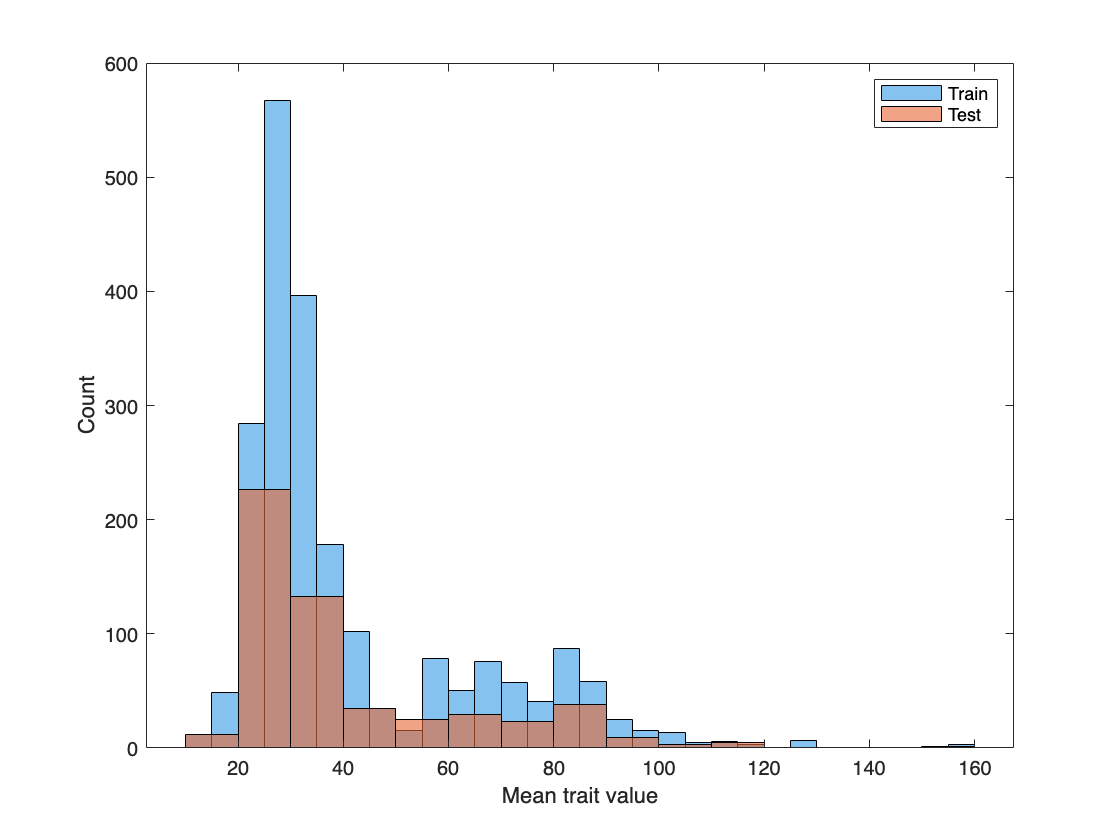

% Histogram
% IMPORTANT(Based on histogram): Stratified split kept the Y distribution consistent across train and test sets.
close all
figure
histogram(y_mean(trainR), 'FaceColor',[0.2 0.6 0.9]);
hold on;
histogram(y_mean(~trainR), 'FaceColor',[0.9 0.4 0.2]);
legend('Train','Test');
xlabel('Mean trait value'); 
ylabel('Count');
hold off;

## Cross Validation to Find Optimal LV

K = 5;                % number of folds
LV_max = 30;          % maximum number of LV
nTrain = size(X_train,1);
nTraits = size(Y_train,2);

cv = cvpartition(nTrain,'KFold',K);

PRESS      = zeros(nTraits, LV_max);
Q2         = zeros(nTraits, LV_max);

for t = 1:nTraits   % A pls model for each trait
    y = Y_train(:,t);

    for k = 1:LV_max
        SSE = 0; SST = 0;

        for fold = 1:K
            idxTr = training(cv, fold);
            idxVa = test(cv, fold);

            % Standardize X and y using training fold
            [Xk, muXk, sdXk] = zscore(X_train(idxTr,:));
            sdXk(sdXk==0) = 1;

            yk = y(idxTr);
            muy = mean(yk); sdy = std(yk);
            if sdy == 0, sdy = 1; end
            yk = (yk - muy) / sdy;

            Xv = (X_train(idxVa,:) - muXk) ./ sdXk;
            yv = (y(idxVa) - muy) / sdy;

            % Fit PLS1 model with k LVs
            [~,~,~,~,BETA] = plsregress(Xk, yk, k);

            % Predict validation fold
            yv_pred = [ones(size(Xv,1),1) Xv] * BETA;

            % Squared errors
            E = yv - yv_pred;
            SSE = SSE + sum(E.^2);
            SST = SST + sum(yv.^2);
        end

        PRESS(t,k) = SSE;
        Q2(t,k)    = 1 - SSE / max(SST, eps);
    end
end

## Visualising

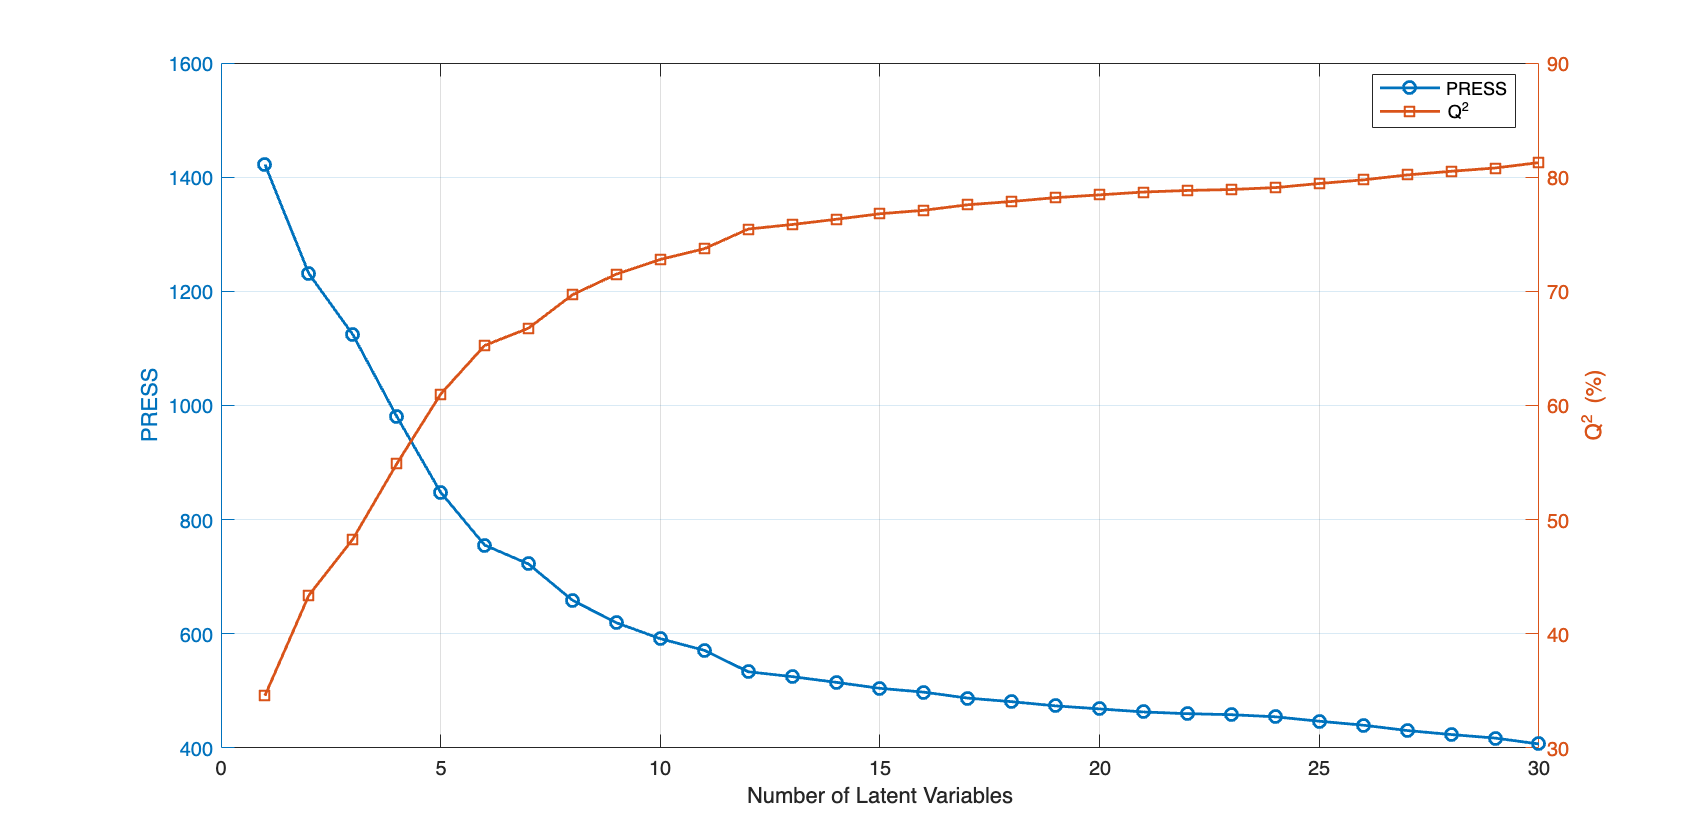

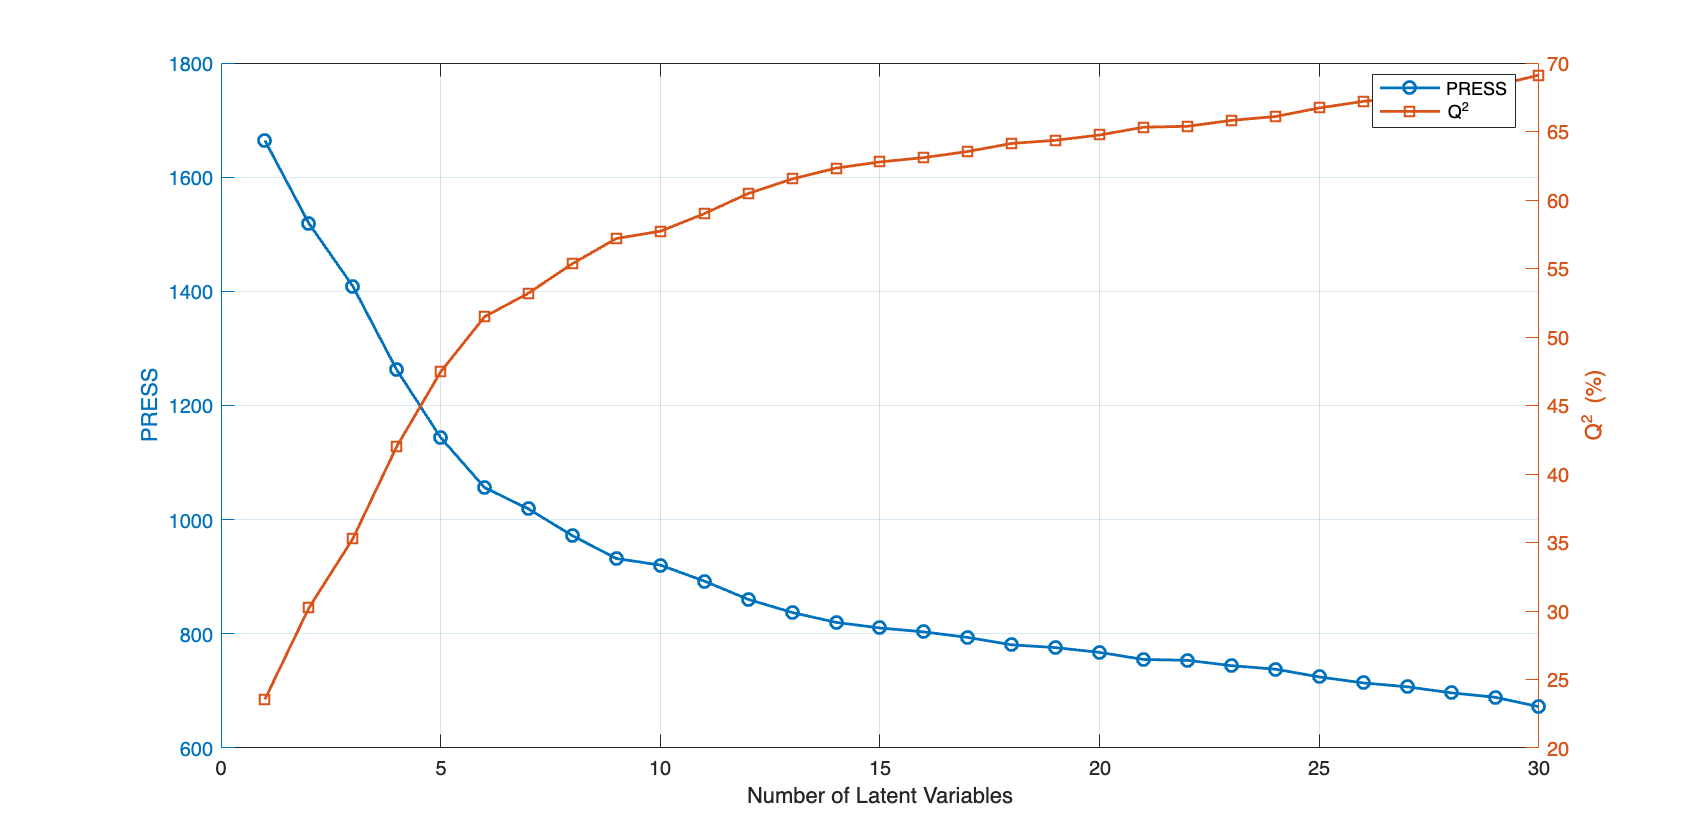

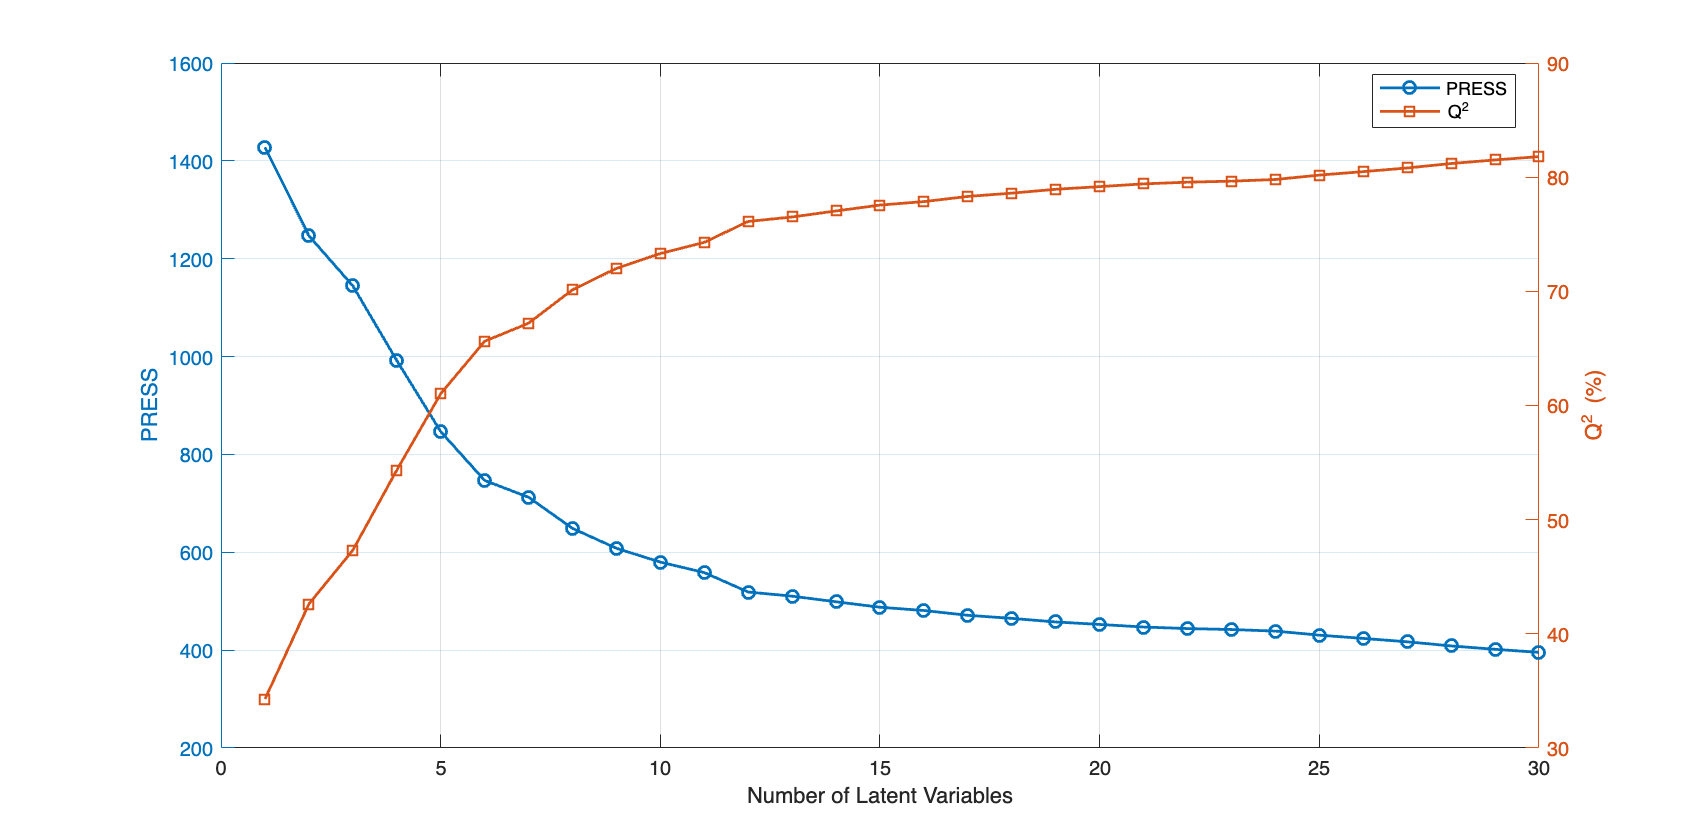

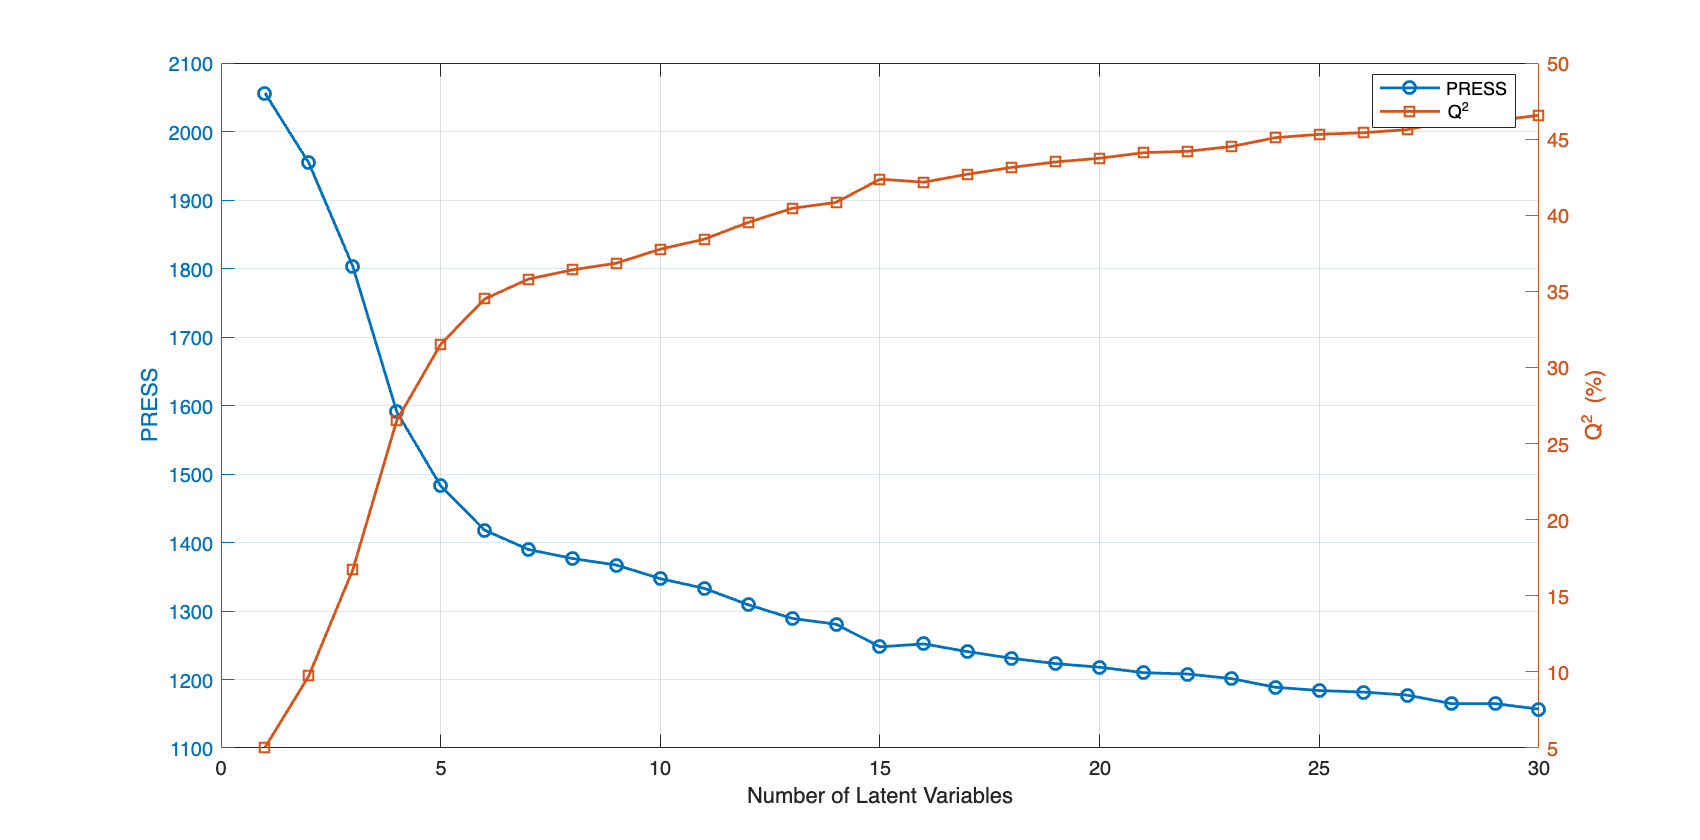

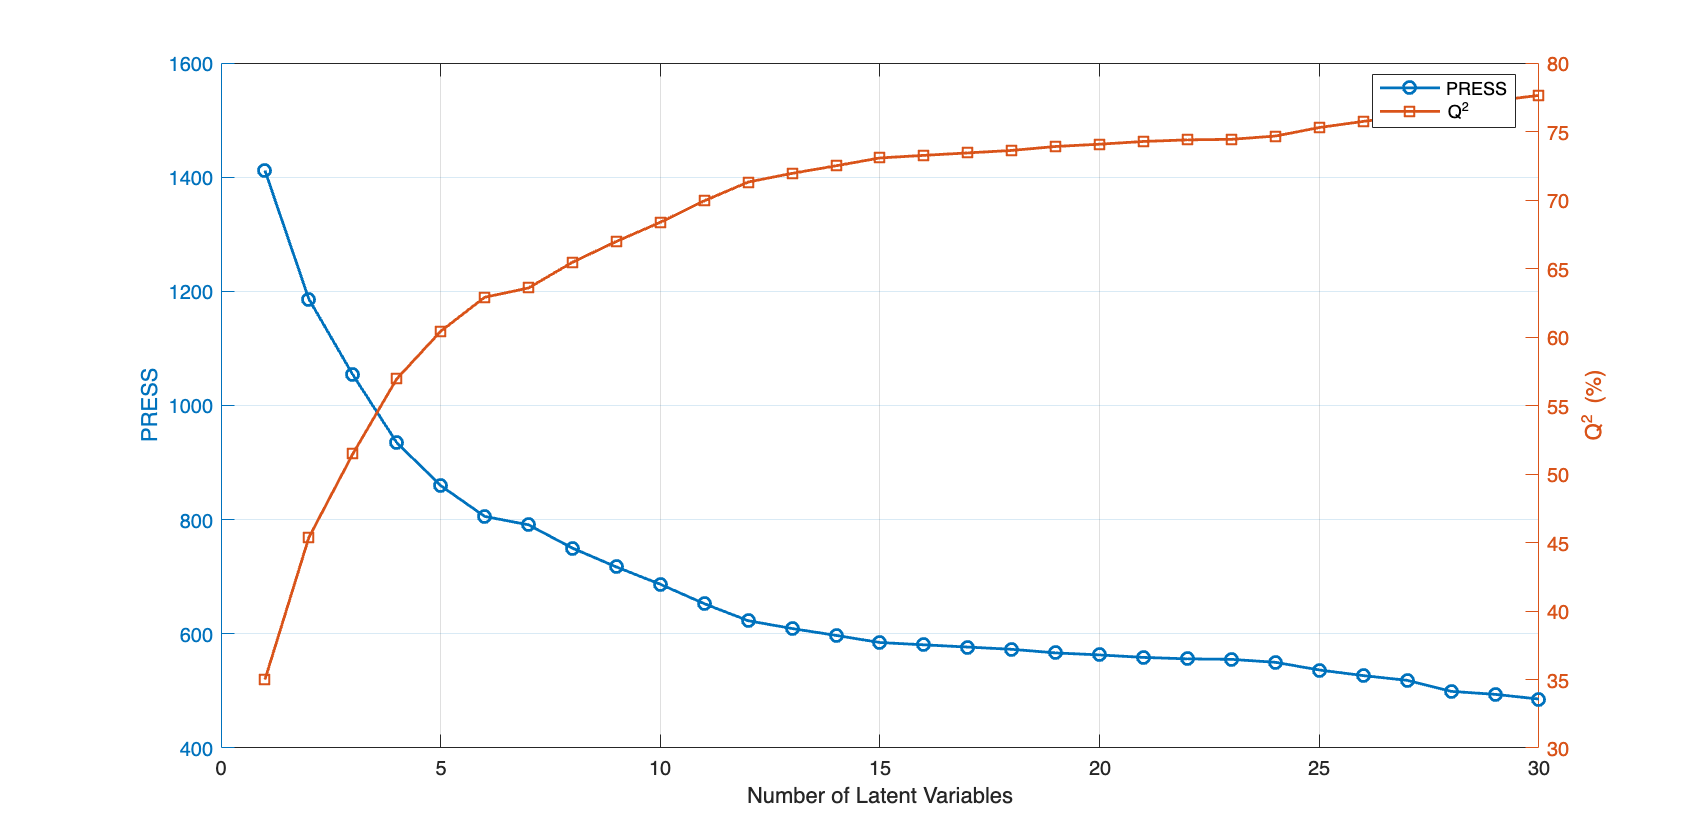

for t = 1:nTraits
    figure('Name',sprintf('PLS - Trait %d',t),'Position',[100 100 850 420]);

    yyaxis left
    plot(1:LV_max, PRESS(t,:), '-o', 'LineWidth', 1.4);
    ylabel('PRESS'); grid on;

    yyaxis right
    plot(1:LV_max, 100*Q2(t,:), '-s', 'LineWidth', 1.4);
    ylabel('Q^{2} (%)');

    xlabel('Number of Latent Variables');
    %title(sprintf('PLS Cross-Validation — Trait %d',t));
    legend('PRESS','Q^{2}','Location','best');
end

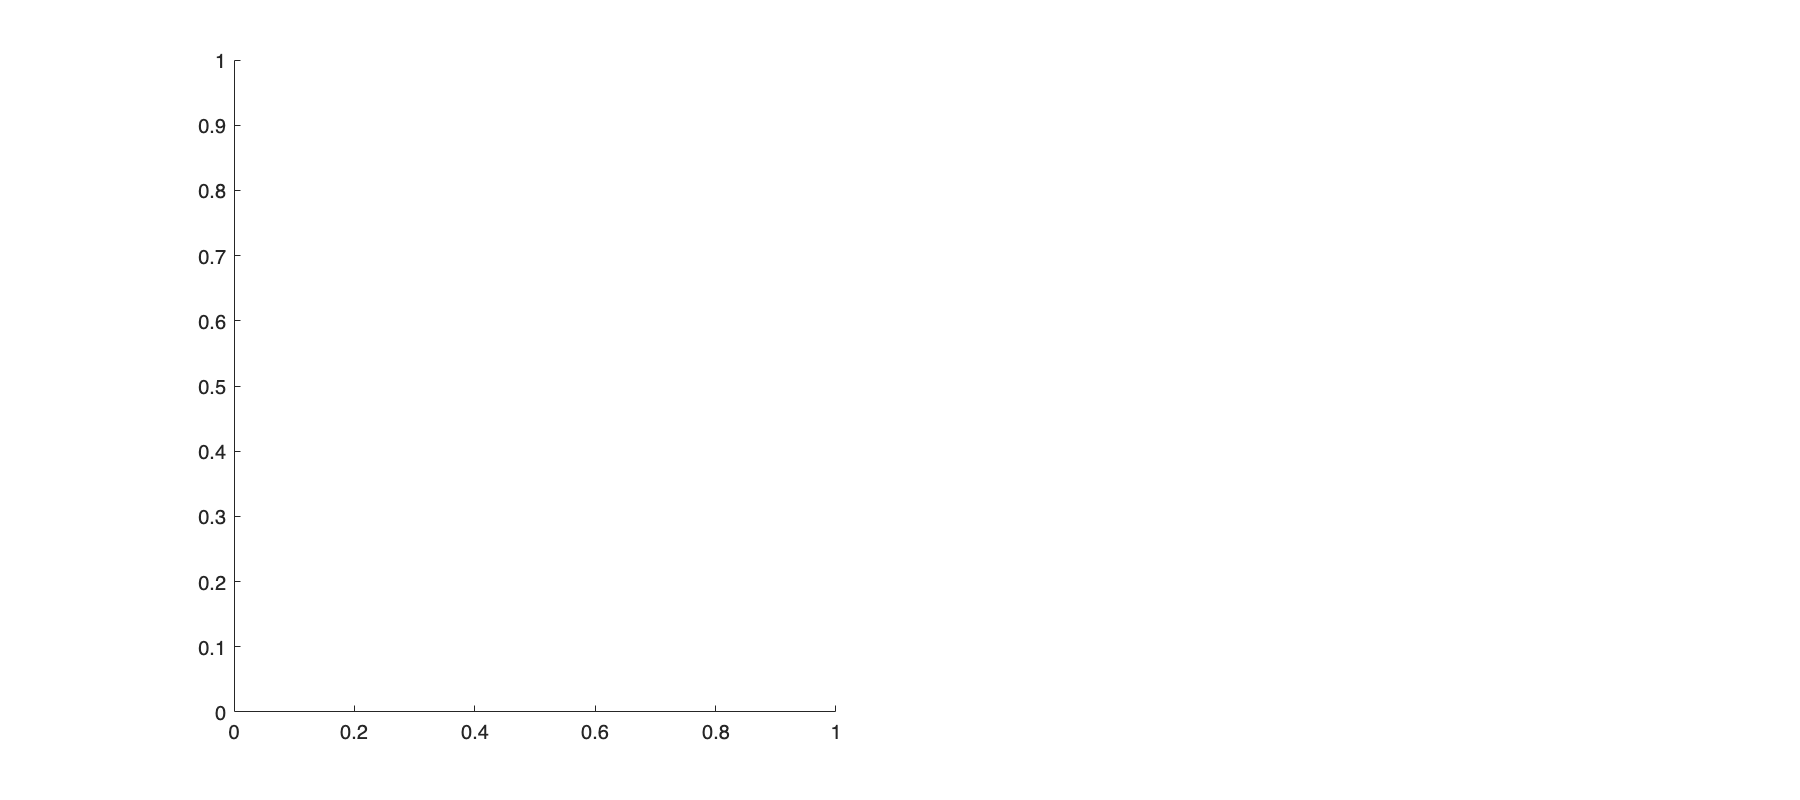

figure('Name','Distributions across folds','Position',[100 100 900 400])
subplot(1,2,1)

%boxchart(repelem(1:LV_max, K)', PRESS_fold(:), 'BoxFaceColor',[0.3 0.6 0.9]);
%xlabel('#LV');
%ylabel('PRESS_{CV} (per fold)');
%title(['PRESS per fold with K=', num2str(K), ' folds']);

%subplot(1,2,2)
%boxchart(repelem(1:LV_max, K)', Q2_fold(:), 'BoxFaceColor',[0.9 0.5 0.3]);
%xlabel('#LV');
%ylabel('Q^{2}_{CV} (per fold)');
%title(['Q^{2} per fold with K=', num2str(K), ' folds']);

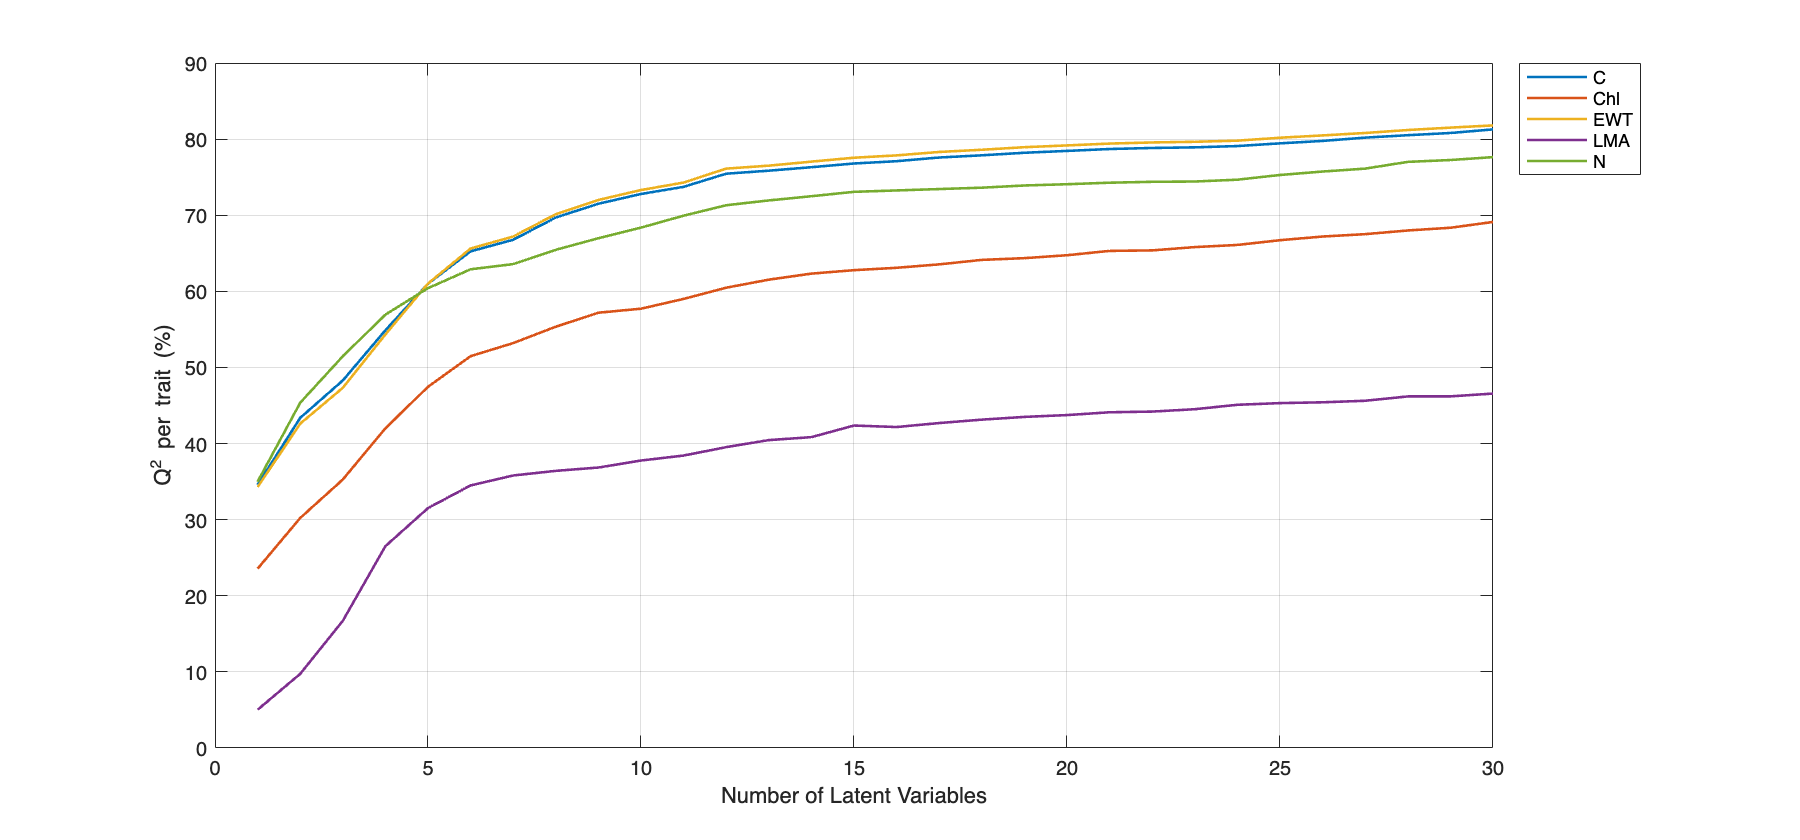

% Per trait Q2
traitLabels = {'C','Chl','EWT','LMA','N'}; 
figure('Name','Per-Trait Q2','Position',[100 100 900 420]);
plot(1:LV_max, 100*Q2', 'LineWidth', 1.3);   % Q2: nTraits x LV_max -> transpose
xlabel('Number of Latent Variables');
ylabel('Q^{2} per trait (%)');
grid on;
legend(traitLabels, 'Location', 'bestoutside');

% IMPORTANT: LV = 10 is optimal here (Q2 and Press)
% IMPORTANT: When looking at per-trait Q2: even 8 looks good for some
% traits

% Try also with 10, 11, 12
% lv_list = [10 11 12];
% for lv = lv_list
    % fprintf('\nQ2 per trait at LV=%d (%%):\n', lv);
    % disp( round(100*Q2_trait(lv,:), 1) );
% end
% IMPORTANT: Not much changes. stay on ten

## Testing with Optimal LV

LV = 10;  
nTraits = size(Y_train,2);

Y_train_pred = zeros(size(Y_train));
Y_test_pred  = zeros(size(Y_test));

R2_train    = zeros(1,nTraits);
RMSE_train  = zeros(1,nTraits);
RMSE_test   = zeros(1,nTraits);
Q2_test     = zeros(1,nTraits);
NRMSE_train = zeros(1,nTraits);
NRMSE_test  = zeros(1,nTraits);

for t = 1:nTraits
    ytr = Y_train(:,t);
    yte = Y_test(:,t);

    % Z-score standardization using train set
    [X_train_Z, muX, sigmaX] = zscore(X_train); 
    X_test_Z = (X_test - muX) ./ sigmaX;

    [ytrZ, muy, sdy] = zscore(ytr);
    if sdy == 0, sdy = 1; end
    yteZ = (yte - muy) ./ sdy;

    % PLS fit
    [XL,YL,XS,YS,BETA] = plsregress(X_train_Z, ytrZ, LV);

    % Predictions in Z-space
    ytrZ_pred = [ones(size(X_train_Z,1),1) X_train_Z]*BETA;
    yteZ_pred = [ones(size(X_test_Z,1),1)  X_test_Z ]*BETA;
    Y_train_pred(:,t) = ytrZ_pred * sdy + muy;
    Y_test_pred(:,t)  = yteZ_pred * sdy + muy;

    % Performance Evaluation: Q2 and RMSE(and normalized RMSE)
    RMSE_train(t) = sqrt(mean((ytr - Y_train_pred(:,t)).^2));
    RMSE_test(t)  = sqrt(mean((yte - Y_test_pred(:,t)).^2));
    Q2_test(t)    = 1 - sum((yte - Y_test_pred(:,t)).^2) / sum((yte - mean(ytr)).^2);

    rangeY = max([ytr; yte]) - min([ytr; yte]);
    if rangeY == 0, rangeY = 1; end
    NRMSE_train(t) = RMSE_train(t) / rangeY;
    NRMSE_test(t)  = RMSE_test(t) / rangeY;
end

disp(table(traitLabels', Q2_test', ...
    RMSE_train', RMSE_test', NRMSE_train', NRMSE_test', ...
    'VariableNames', {'Trait','Q2_test','RMSE_train','RMSE_test','NRMSE_train','NRMSE_test'}));

     Trait     Q2_test    RMSE_train    RMSE_test    NRMSE_train    NRMSE_test
    _______    _______    __________    _________    ___________    __________

    {'C'  }    0.72218       47.676       48.934      0.075635       0.077632 
    {'Chl'}    0.56017     0.071477     0.075929      0.086168       0.091536 
    {'EWT'}    0.72779       2.6488       2.7492      0.074161       0.076971 
    {'LMA'}    0.32545       9.8273       9.7341       0.10461        0.10362 
    {'N'  }     0.6915       6.4979       6.3292      0.080826       0.078728 



## Visualsing

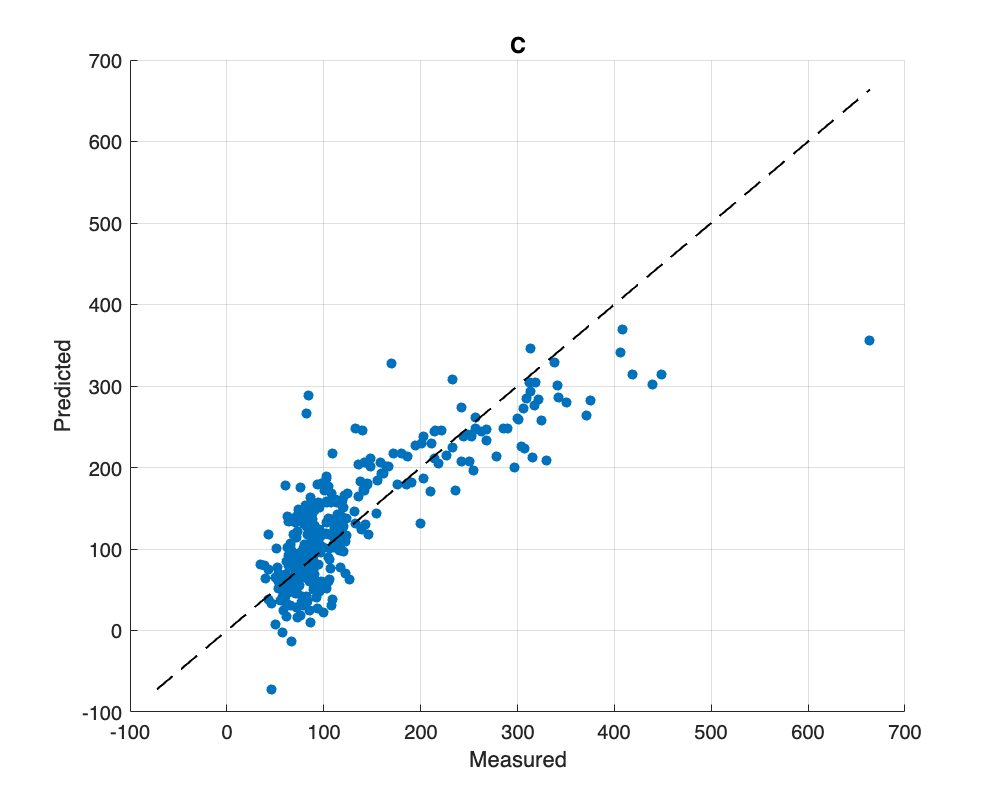

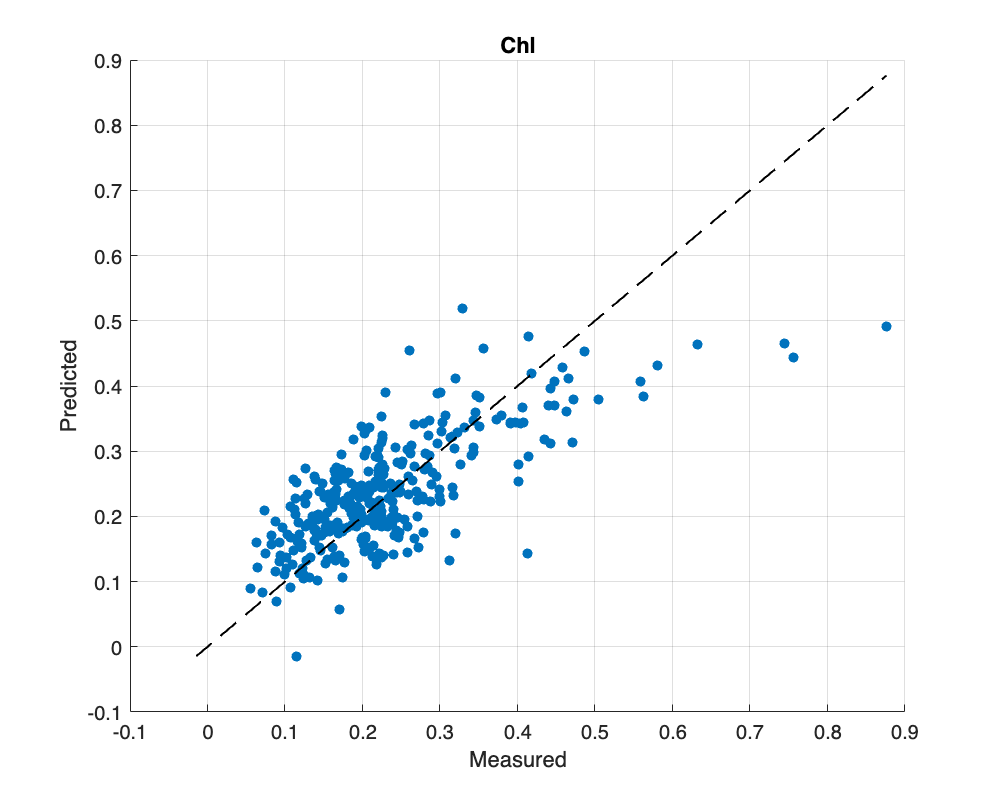

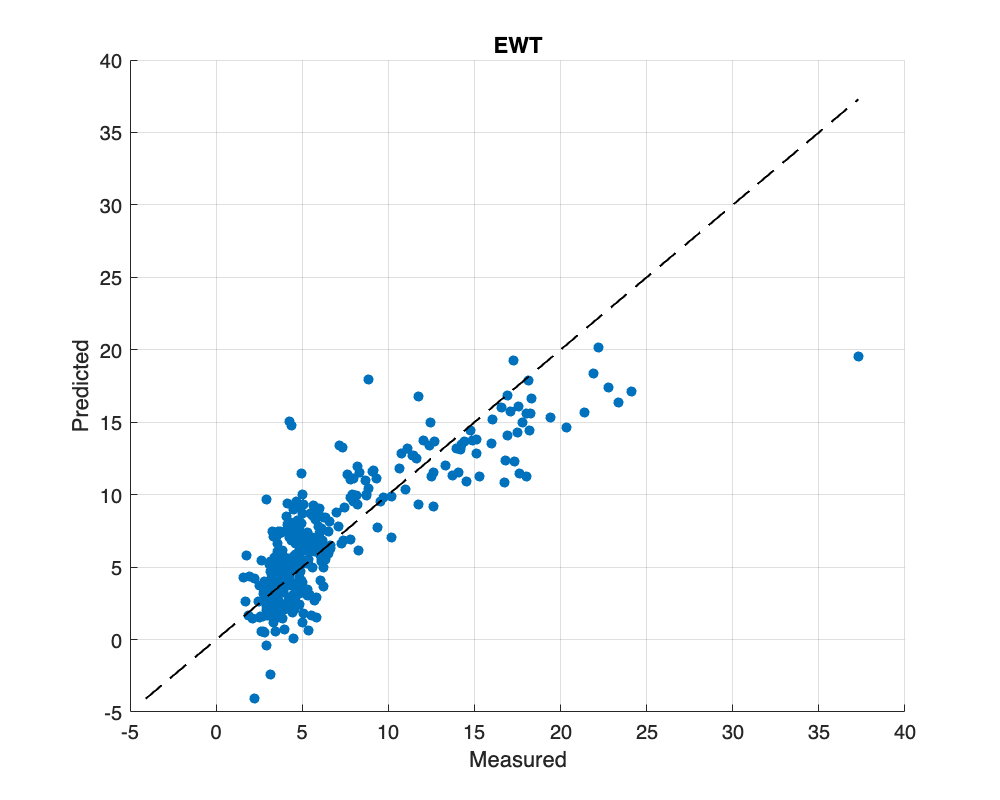

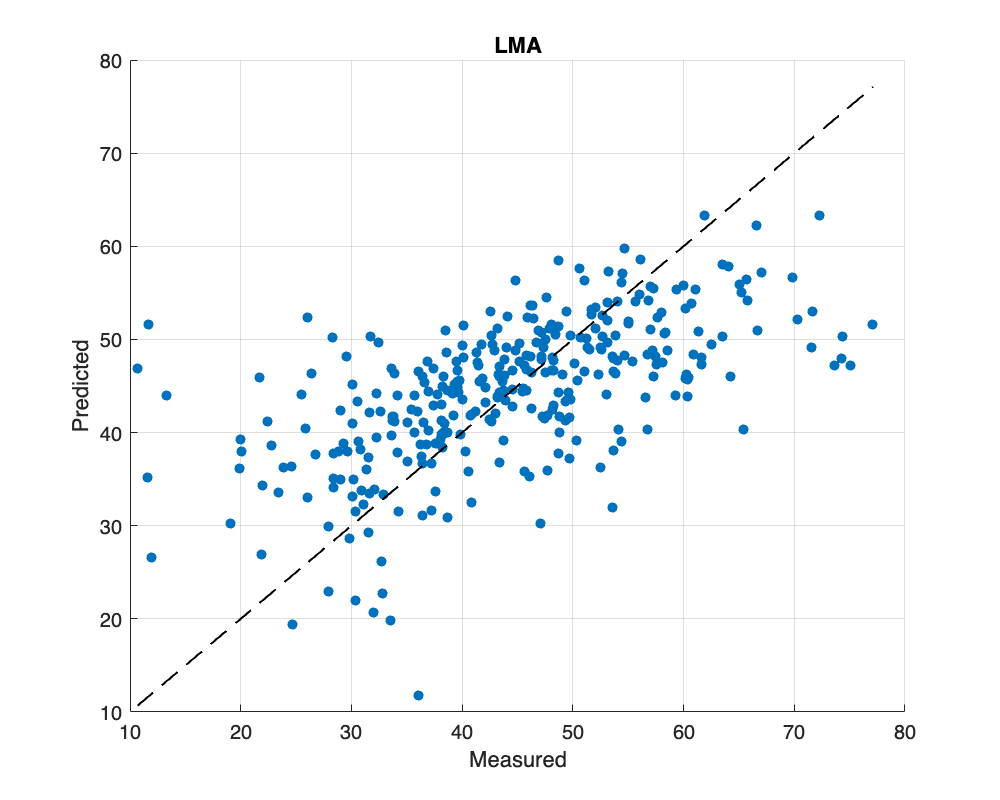

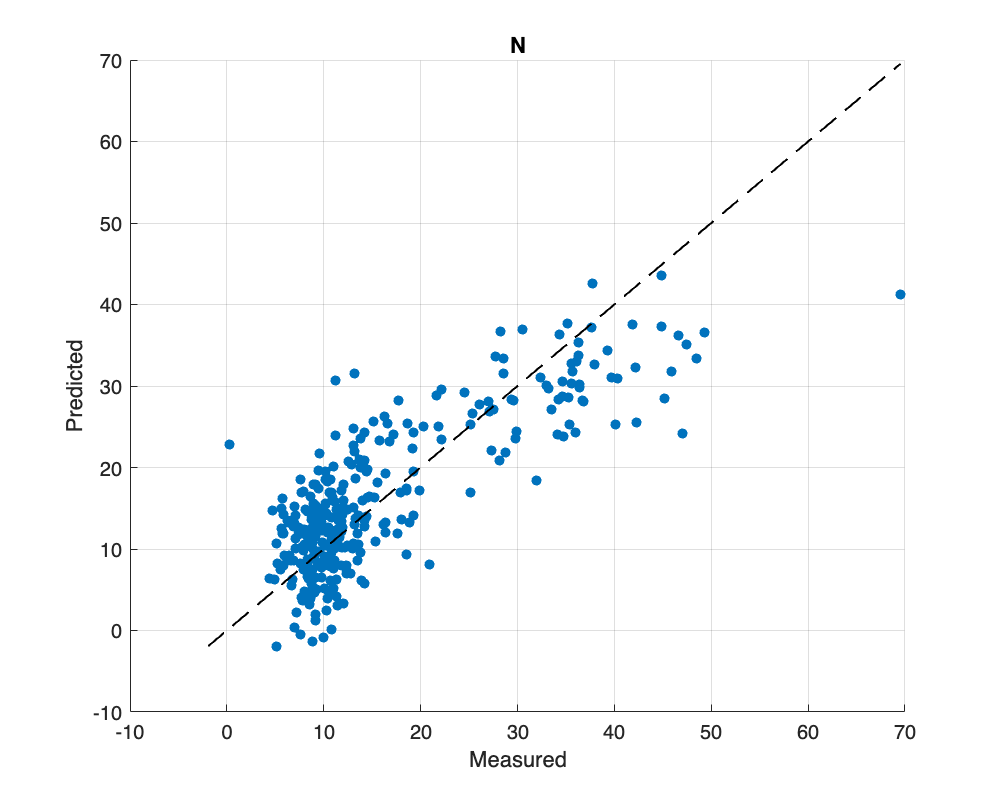

for i = 1:nTraits
    f = figure('Name',sprintf('Measured vs Predicted - %s', traitLabels{i}), ...
               'Position',[100 100 500 400]);
    grid on; hold on
    scatter(Y_test(:,i), Y_test_pred(:,i), 25, 'filled');
    lims = [min([Y_test(:,i); Y_test_pred(:,i)]) max([Y_test(:,i); Y_test_pred(:,i)])];
    plot(lims, lims, 'k--','LineWidth',1);
    xlabel('Measured'); ylabel('Predicted');
    title(sprintf('%s', traitLabels{i}));
    
    saveas(f, sprintf('Scatter_%s.png', traitLabels{i}));
end

% IMPORTANT: Almost perfect predictions: But CHL the worst overall

for t = 1:nTraits
    [~,~,~,~,BETA] = plsregress(X_train, Y_train(:,t), LV);

    beta_norm = BETA(2:end) ./ norm(BETA(2:end));

    % Plot
    f = figure('Name',sprintf('PLS Coefficients - %s', traitLabels{t}), ...
               'Position',[100 100 900 400]);
    plot(beta_norm,'LineWidth',1.5);
    xlabel('Wavelength index'); % Eğer dalga boyu vektörün varsa onu koy
    ylabel('Coefficient (normalized)');
    grid on;
    title(sprintf('Normalized PLS Coefficients (%s)', traitLabels{t}));
    saveas(f, sprintf('Beta_%s.png', traitLabels{t}));
end

Unrecognized function or variable 'Y_train_Z'.

% Important: Most traits (LMA, C, N, EWT) share similar coefficient patterns, indicating overlapping spectral information in NIR regions.
% Important: Chlorophyll content behaves differently, showing distinct peaks in the visible range (around 450–700 nm).
% Important: Strong peaks near 1350 nm highlight water absorption bands, confirming EWT’s dominant influence in that region.


%% Latent Variable Scores (T1 vs T2)

% Uses XS from plsregress output (scores of X)
T_scores = XS(:, 1:2);  % first two LV

% Explained variance (X-side)
explVarX = 100 * cumsum(PCTVAR(1, 1:2));  

figure('Name','Latent Variable Scores (T1 vs T2)','Position',[100 100 800 600]);
scatter(T_scores(:,1), T_scores(:,2), 25, 'filled', 'MarkerFaceAlpha', 0.6);
grid on; box on;
colorbar;
xlabel(sprintf('LV1 (%.1f%% X variance)', explVarX(1)));
ylabel(sprintf('LV2 (%.1f%% X variance)', explVarX(2)));
title('PLS2 Scores Plot (T1 vs T2)');

%% Loadings Plot (W and Q)

% W = X loadings (predictor space)
% Q = Y loadings (response space)
W_load = XL(:, 1:2);   % first 2 LV for X
Q_load = YL(:, 1:2);   % first 2 LV for Y


figure('Name','PLS2 Loadings Plot (LV1 vs LV2)','Position',[100 100 800 600]); hold on;
scatter(W_load(:,1), W_load(:,2), 15, 'b', 'filled', 'MarkerFaceAlpha', 0.4);
scatter(Q_load(:,1), Q_load(:,2), 70, 'r', 'filled', 'MarkerEdgeColor','k');
legend({'X loadings (spectral bands)','Y loadings (traits)'}, 'Location','best');
xlabel('LV1 Loading');
ylabel('LV2 Loading');
title('PLS2 Loadings Plot (X vs Y variables)');
grid on; box on;

% Add labels for Y traits
for i = 1:size(Q_load,1)
    text(Q_load(i,1), Q_load(i,2), sprintf('  %s', traitLables{i}), 'Color','r', 'FontSize',10, 'FontWeight','bold');
end
%  Most traits cluster closely, indicating shared spectral information, while Chl content is clearly separated — showing its distinct spectral behavior in the visible region.

%% Normalized Loadings Biplot (W–Q combined)
% Normalize X and Y loadings to unit length for comparability

Wn = XL(:,1:2);
Qn = YL(:,1:2);

% Normalize columns
Wn = Wn ./ vecnorm(Wn);
Qn = Qn ./ vecnorm(Qn);

figure('Name','Normalized PLS2 Loadings Biplot (LV1 vs LV2)','Position',[100 100 800 600]); hold on;
scatter(Wn(:,1), Wn(:,2), 15, 'b', 'filled', 'MarkerFaceAlpha', 0.3);
scatter(Qn(:,1), Qn(:,2), 70, 'r', 'filled', 'MarkerEdgeColor','k');

xlabel('LV1 (normalized loading)');
ylabel('LV2 (normalized loading)');
title('Normalized PLS2 Loadings Biplot (W–Q combined)');
legend({'Spectral bands (X)','Traits (Y)'}, 'Location','best');
grid on; box on;

% Add Y labels
% IMPORTANT: This normalized PLS2 biplot visualizes the joint space of spectral and trait loadings (W–Q) on a common scale. It supports the previous loading plot, showing that chlorophyll behaves spectrally distinct, while LMA, C, N, and EWT cluster together due to similar structural information.
for i = 1:size(Qn,1)
    text(Qn(i,1)+0.01, Qn(i,2), sprintf('%s', traitLables{i}), 'Color','r', 'FontWeight','bold');
end

%% Variable Importance in Projection (VIP) 
% Compute VIP scores for each spectral band

Yz = (Y - muY) ./ sigmaY; % Restandardization of Y
T = XS;  % scores from PLS2 model
W = XL;  % X loadings
Q = YL;  % Y loadings

SSY = sum((Yz * YL).^2, 1);  % Sum of squares for Y explained by each LV
Wnorm = sqrt(sum(W.^2, 1));  % normalize weights per LV

VIP = zeros(size(W,1),1);
for i = 1:size(W,1)
    VIP(i) = sqrt(size(W,1) * sum(SSY .* (W(i,:).^2 ./ Wnorm.^2)) / sum(SSY));
end

% Plot
figure('Name','VIP Scores per Spectral Band','Position',[100 100 900 400]);
plot(VIP, 'LineWidth', 1.2, 'Color', [0 0.45 0.74]); hold on;
yline(1, 'r--', 'LineWidth',1.1, 'Label','VIP = 1 (important threshold)', 'LabelHorizontalAlignment','left');
xlabel('Spectral Band Index');
ylabel('VIP Score');
title('Variable Importance in Projection for PLS2 Model');
grid on;  
% Important: It shows which wavelength regions matter most for predicting traits. Above the VIP = 1 line mark the spectral bands that carry the strongest information and have the biggest impact on the model’s performance.